% чтение чисел Вольфа
fid = fopen('wolf.dat', 'r');
if fid == -1
    error('File is not opened');
end

[sunspot,N]=fscanf(fid,' %d %d %d %d \n',[4 inf]);
fclose(fid);


% для записи на обработку в cuda и си код
% fid = fopen('wolf1.dat', 'w');
% if fid == -1
%     error('File is not opened');
% end
% fprintf(fid,'%d %d %d %d\n', sunspot);
% fclose(fid);


n = length(sunspot);

sunspot_disk = sunspot(3, 1:end);
sunspot_center = sunspot(4, 1:end);

sunspot_disk(sunspot_disk==999)=0;
sunspot_center(sunspot_center==999)=0;

avg = (sunspot_disk + sunspot_center)/2

avg =    42.5000   43.0000   34.5000   38.0000   51.0000   42.5000   31.5000   53.0000   38.0000   66.0000         0         0   52.0000         0   53.5000   42.5000   60.5000         0   50.0000   46.5000   59.5000         0   79.5000   52.0000   36.0000   25.5000   24.0000   20.0000   32.0000   30.0000   32.0000   41.0000   42.0000   41.0000   47.5000   42.5000   37.5000   50.5000   41.0000   56.5000   64.5000   81.5000   53.0000   74.5000         0   91.0000  125.5000  116.5000  115.0000   85.0000


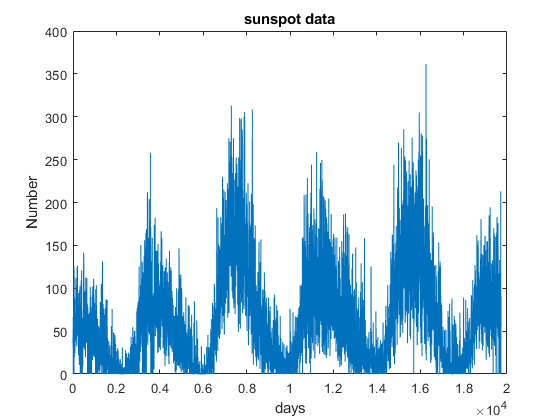



relNums = avg;

day = [1:1:n];

plot(day, relNums)
xlabel('days')
ylabel('Number')
title('sunspot data')


fid = fopen('wolf_fft.dat', 'r');
if fid == -1
    error('File is not opened');
end

[wolf_fft,N]=fscanf(fid,'%f %f\n',[2 inf]);
fclose(fid);

res = wolf_fft(1, 1:end) + i*wolf_fft(2, 1:end)

res = 	1.0e+06 *

   1.1938 + 0.0000i  -0.1028 + 0.0674i  -0.0431 + 0.1443i   0.0188 - 0.0707i  -0.0662 - 0.0740i   0.4966 + 0.1678i  -0.0322 - 0.0366i  -0.1169 + 0.1016i  -0.0204 - 0.0205i  -0.0239 - 0.0098i  -0.0405 + 0.0919i   0.0183 - 0.0181i  -0.0140 - 0.0041i   0.0003 - 0.0134i  -0.0193 + 0.0210i  -0.0131 - 0.0292i  -0.0083 - 0.0027i   0.0346 + 0.0130i  -0.0053 + 0.0061i   0.0033 - 0.0162i   0.0144 - 0.0011i  -0.0080 + 0.0007i   0.0152 + 0.0181i  -0.0113 + 0.0238i   0.0015 - 0.0073i  -0.0008 - 0.0017i  -0.0138 + 0.0057i   0.0042 + 0.0055i   0.0071 + 0.0111i  -0.0166 + 0.0154i   0.0027 - 0.0168i  -0.0018 + 0.0100i  -0.0055 + 0.0026i   0.0040 - 0.0070i  -0.0168 - 0.0025i   0.0102 + 0.0079i   0.0137 - 0.0073i  -0.0170 + 0.0178i   0.0057 + 0.0117i  -0.0128 + 0.0111i   0.0065 - 0.0002i   0.0157 - 0.0186i  -0.0187 + 0.0016i   0.0073 + 0.0079i   0.0052 + 0.0089i  -0.0138 - 0.0015i  -0.0014 - 0.0219i  -0.0118 - 0.0067i  -0.0058 - 0.0066i  -0.0103 - 0.0173i


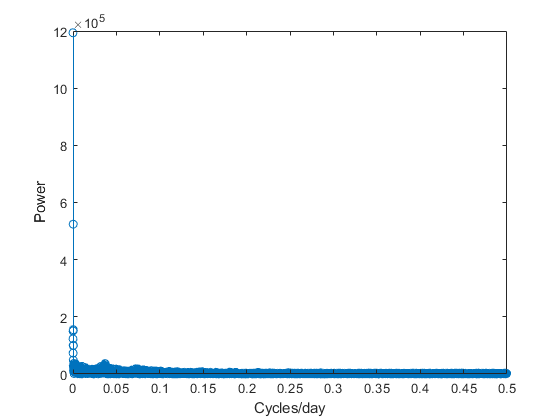


e = res(1:floor(n/2)+1);
Fs=1;
f=linspace(0, Fs/2, floor(n/2)+1);
stem(f, abs(e)) % abs - magnitude or power
xlabel('Cycles/day')
ylabel('Power')

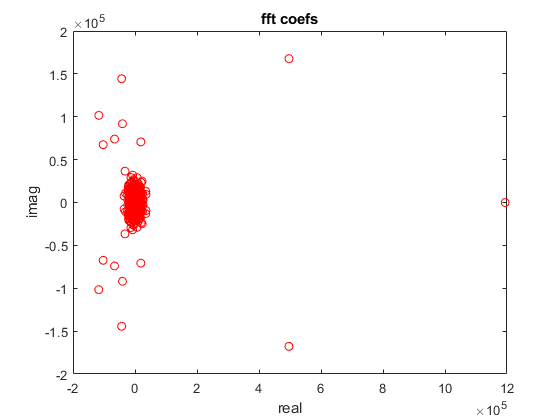


% res(1) = [];
plot(res, 'ro')
xlabel('real')
ylabel('imag')
title('fft coefs')

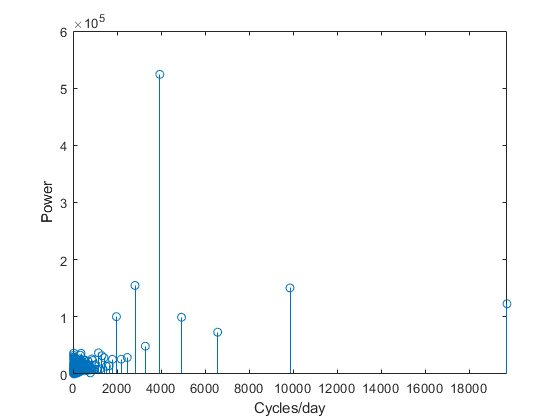



period = 1./f;
stem(period, abs(e));
xlim([0 n])
xlabel('Cycles/day')
ylabel('Power')